# Qc

clear; clc; close all;

**Step 1. Input Data and Parameters**

Hypothesized population mean (μ0) = 120 Significance level α = 0.05

alpha  = 0.05;
mu0    = log(120)

mu0 = 4.7875


% The intervals between breakdowns (in working hours) of three such cranes, of different ages, in recent weeks.
craneA = [140 140 112 90 32 154 359 207 61 39 40];
craneB = [69 14 38 94 46 36 84 106 269 445 42 108 244 92 148 303 24 328 207 260 132 56];
craneC = [39 135 57 31 190 90 293 151 26 77 82 156 328 92 138 47 45];

% Based on the answer (b), we can conclude that there is no significant difference among the three groups.
crane_all_o = [craneA, craneB, craneC];
crane_all   = log(crane_all_o);

**Step 2. Descriptive Statistics**

n    = numel(crane_all);          % Sample size
xbar = mean(crane_all);           % Sample mean
s    = std(crane_all, 0);         % Sample standard deviation (n-1)
SE   = s / sqrt(n);               % Standard error
df   = n - 1;                     % Degrees of freedom

% Additional descriptive measures
medianVal = median(crane_all);
modeVal   = mode(crane_all);
variance  = var(crane_all);
rangeVal  = range(crane_all);
minVal    = min(crane_all);
maxVal    = max(crane_all);
sumVal    = sum(crane_all);

**Step 3. Display Descriptive Results**

fprintf('\n---  Descriptive Statistics ---\n');


---  Descriptive Statistics ---


fprintf('Sample size (n): %d\n', n);

Sample size (n): 50


fprintf('Mean (x̄): %.2f\n', xbar);

Mean (x̄): 4.56


fprintf('Median: %.2f | Mode: %.2f\n', medianVal, modeVal);

Median: 4.53 | Mode: 3.66


fprintf('Standard deviation (s): %.3f\n', s);

Standard deviation (s): 0.822


fprintf('Standard error (SE): %.3f\n', SE);

Standard error (SE): 0.116


fprintf('Variance: %.3f | Range: %.2f | Min: %.2f | Max: %.2f\n', variance, rangeVal, minVal, maxVal);

Variance: 0.675 | Range: 3.46 | Min: 2.64 | Max: 6.10


fprintf('Sum: %.2f | Degrees of freedom: %d\n', sumVal, df);

Sum: 227.91 | Degrees of freedom: 49


**Step 4. Histogram and boxplot to explore distribution**

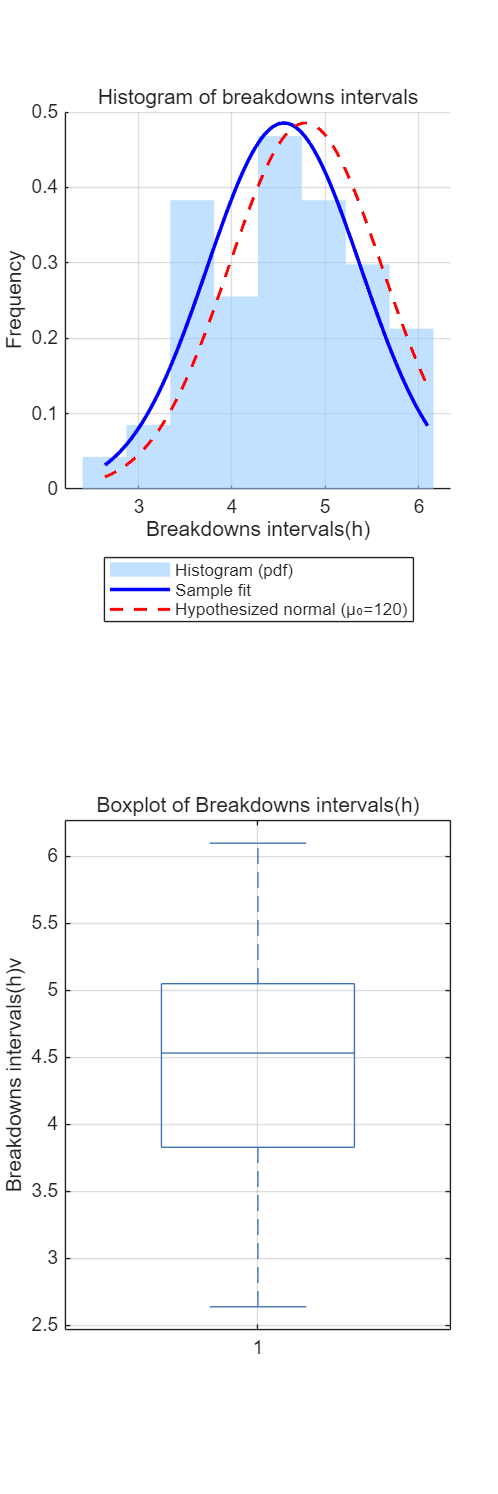

figure('Color','w','Position',[100 100 400 1200]);%('Name','Descriptive Plots','Color','w')
subplot(2,1,1); hold on;
histogram(crane_all, 8, ...
    'Normalization','pdf', ...           
    'FaceColor',[0.6 0.8 1], 'EdgeColor','none');

xx_0 = linspace(min(crane_all), max(crane_all), 300);
plot(xx_0, normpdf(xx_0, mean(crane_all), std(crane_all,0)), ...
    'b-', 'LineWidth', 1.8);

plot(xx_0, normpdf(xx_0, mu0, std(crane_all,0)), ...
    'r--', 'LineWidth', 1.5);
xlabel('Breakdowns intervals(h)'); 
ylabel('Frequency');
title('Histogram of breakdowns intervals'); 
legend('Histogram (pdf)', 'Sample fit', 'Hypothesized normal (μ₀=120)', 'Location','southoutside');
grid on; 

subplot(2,1,2)
boxplot(crane_all,...
    'Colors',[0.25 0.45 0.7], 'Widths',0.5);
ylabel('Breakdowns intervals(h)v'); 
title('Boxplot of Breakdowns intervals(h)'); 
grid on;

**Step 5. One-Sample t-Test (Manual Calculation)**

Compute t-statistic. **Test Statistic:  **$t=\frac{\bar{x} -\mu_0 }{\hat{\sigma} /\sqrt{n}}$, where $\bar{x}$ is the sample mean, $\hat{\sigma}$ is the sample standard deviation, $n$ is sample size and the Degrees of freedom is n-1. Decision rule:

- If $\left|t\right|>t_{\textrm{critical}}$ or $p<\alpha$: Reject $H_0$

- Otherwise: Fail to reject $H_0$

t_stat = (xbar - mu0) / SE;
% Two-tailed p-value
if exist('tcdf','file')==2
    p_right = 1 - tcdf(t_stat, df);
else
    p_right = 1 - normcdf(t_stat, 0, 1);
end
% Critical t-value (Right-tailed)
if exist('tinv','file')==2
    t_crit = tinv(1 - alpha, df);
else
    t_crit = norminv(1 - alpha, 0, 1);
end

% 95% Confidence Interval for μ
CI = [xbar - t_crit*SE, Inf];
% Decision Rule
if p_right < alpha
    decision = "Reject H0 (evidence mean > 120h)";
else
    decision = "Fail to reject H0 (no significant evidence mean > 120h)";
end

**Step 6. Display t-Test Results**

fprintf('\n--- One-Sample t-Test Results ---\n');


--- One-Sample t-Test Results ---


fprintf('t-statistic = %.4f | df = %d\n', t_stat, df);

t-statistic = -1.9733 | df = 49


fprintf('Right-tailed p-value = %.4f\n', p_right);

Right-tailed p-value = 0.9729


fprintf('t-critical (one-tail, α=%.2f) = %.3f\n', alpha, t_crit);

t-critical (one-tail, α=0.05) = 1.677


fprintf('95%% Confidence Interval for μ: [%.2fh, Inf]\n', xbar - t_crit*SE);

95% Confidence Interval for μ: [4.36h, Inf]


fprintf('Decision: %s\n', decision);

Decision: Fail to reject H0 (no significant evidence mean > 120h)



% Summarize in a table
ResultsTable = table(n, xbar, s, SE, df, t_stat, t_crit, p_right, ...
                     CI(1), CI(2), string(decision), ...
    'VariableNames', {'n','Mean','StdDev','StdError','df','t_stat','t_crit', ...
                      'p_value','CI_Lower','CI_Upper','Decision'});
disp(ResultsTable);

    n      Mean     StdDev     StdError    df    t_stat     t_crit    p_value    CI_Lower    CI_Upper                            Decision                         
    __    ______    _______    ________    __    _______    ______    _______    ________    ________    _________________________________________________________

    50    4.5581    0.82188    0.11623     49    -1.9733    1.6766    0.97294     4.3633       Inf       "Fail to reject H0 (no significant evidence mean > 120h)"



**Step 7. Visualize the t-Distribution**

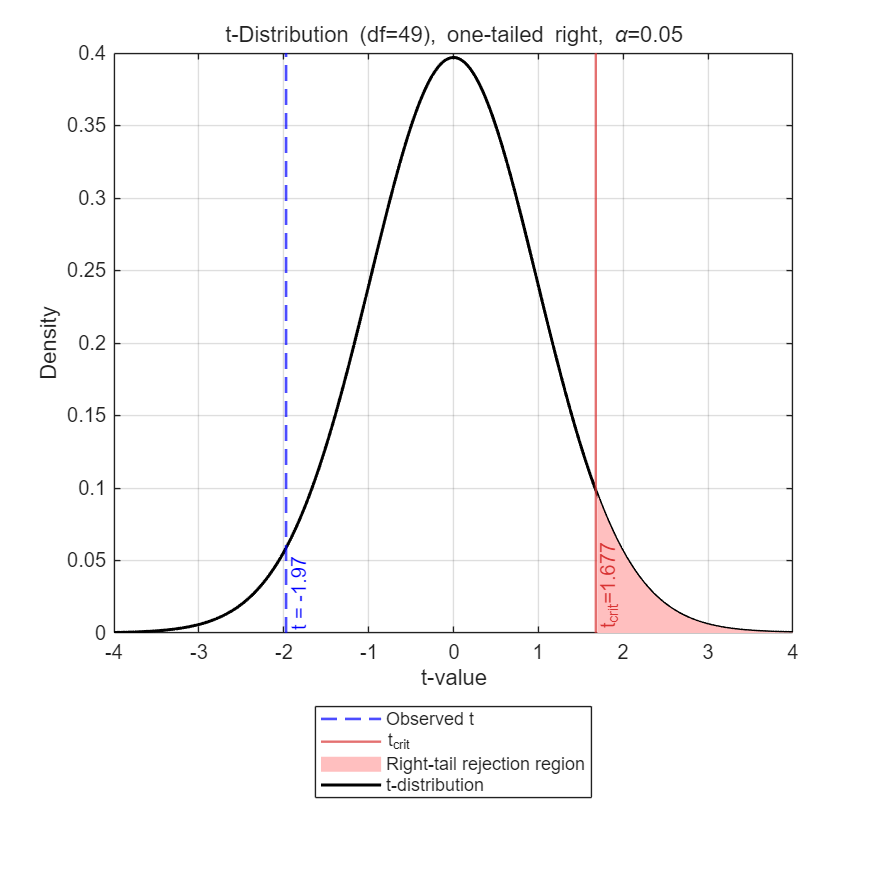

x = linspace(-4,4,400);
if exist('tpdf','file')==2
    pdf_t = tpdf(x, df);
else
    pdf_t = normpdf(x, 0, 1);
end

figure('Color','w','Position',[100 100 900 900]);
plot(x, pdf_t, 'k', 'LineWidth', 1.5); hold on; grid on;

% Rejection regions (α right side)
idxR = x > t_crit;
area(x(idxR), pdf_t(idxR), 'FaceColor',[1 0.75 0.75], 'EdgeColor','none');

% Ctitical line
xline(t_crit, '-', sprintf('t_{crit}=%.3f', t_crit), ...
    'LineWidth',1.2, 'Color',[0.85 0.2 0.2], 'LabelVerticalAlignment','bottom');
% Observed t-statistic line
xline(t_stat, '--b', sprintf('t = %.2f', t_stat), ...
    'LineWidth',1.3, 'LabelVerticalAlignment','bottom');

xlabel('t-value'); ylabel('Density');
title(sprintf('t-Distribution (df=%d), one-tailed right, \\alpha=%.2f', df, alpha));
legend('t-distribution','Right-tail rejection region','t_{crit}','Observed t', ...
       'Location','southoutside');
hold off;

**Step 8. Interpretation **

fprintf('\n--- Interpretation (One-tailed: H1: μ > %.2f ) ---\n', mu0);


--- Interpretation (One-tailed: H1: μ > 4.79 ) ---


fprintf('Sample mean = %.2f (n = %d) vs. hypothesized mean > %.2f\n', xbar, n, mu0);

Sample mean = 4.56 (n = 50) vs. hypothesized mean > 4.79


fprintf('t = %.4f, p = %.4f\n', t_stat, p_right);

t = -1.9733, p = 0.9729


fprintf('t-critical (one-tail, α=%.2f) = %.3f\n', alpha, t_crit);

t-critical (one-tail, α=0.05) = 1.677


fprintf('95%% two-sided CI for μ = [%.4f, +∞） \n', t_crit);

95% two-sided CI for μ = [1.6766, +∞） 


if p_right < alpha
    fprintf('→ Reject H0: mean runtime is significantly GREATER than %.0f h.\n', mu0);
else
    fprintf('→ Fail to reject H0: no significant evidence that mean runtime > 120 h.\n');
end

→ Fail to reject H0: no significant evidence that mean runtime > 120 h.


% Normality test for each crane
[hA,pA] = lillietest(log(crane_all))

hA = 0

pA = 0.2944